# Actividad 2: Modelado de Energía Cinética

## Objetivo

Para esta actividad se debe obtener el modelo de la energía cinética total para tres configuraciones de robots manipuladores, en este caso el robot cartesiano de tres grados de libertad:

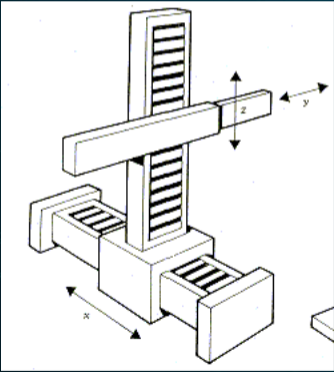

Imagen 1. Modelo

### Procedimiento

Primero se limpia la pantalla y valores, para poder declarar las variables simbólicas, es decir, no tienen un valor en específico.

%Limpieza de pantalla
clear all
close all
clc

tic
%Declaración de variables simbólicas
syms long1(t) long2(t) long3(t)  t %Angulos de cada articulación
syms m1 m2 m3 Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2 Ixx3 Iyy3 Izz3 %Masas y matrices de Inercia
syms t1 t2 t3 %Tiempos
syms l1 l2 l3 lc1 lc2 lc3  %l=longitud de eslabones y lc=distancia al centro de 
% masa de cada eslabón
syms pi g

Posterioremente se hace la configuración del robot, 0 para junta rotacional, 1 para junta prismática, además de crear el vector de coordenadas articulares (Posición). En este caso, como son 3 articulaciones se colocan 3 unos por ser articulaciones prismáticas.

RP=[1 1 1];

Q= [long1; long2; long3];
disp('Coordenadas generalizadas');

Coordenadas generalizadas


pretty (Q);

/ long1(t) \
|          |
| long2(t) |
|          |
\ long3(t) /



Sacando la derivada del vector de coordenadas articulares con la función diff, obtenemos la velocidad articular.

Qp= diff(Q, t);%diff() para derivadas con variable de referencia 
% que no depende de otra: ejemplo el tiempo
disp('Velocidades generalizadas');

Velocidades generalizadas


pretty (Qp);

/  d          \
| -- long1(t) |
| dt          |
|             |
|  d          |
| -- long2(t) |
| dt          |
|             |
|  d          |
| -- long3(t) |
\ dt          /



Con la función size se declara el número de grados de libertad que tiene el robot con el vector RP previamente definido, siempre se coloca 2, ya que indica la dimensión de las columnas y se convierte a string para posteriormente declarar el nombre a las matrices.

GDL= size(RP,2);
GDL_str= num2str(GDL);


Para determinar las matrices de rotación se pone un sistema de referencia en cada articulación empezando desde la base del robot, se coloca el eje z en paralelo con el movimiento de esa articulación y se rota en las demás articulaciones, con esta rotación se determina el ángulo que se sustituirá en las siguientes matrices, dependiendo de en qué eje rotó el sistema de coordenadas.

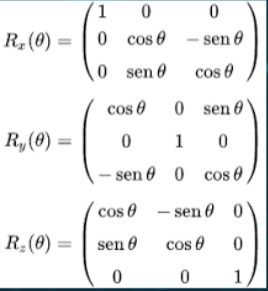

Imagen 2. Matrices de rotación

NOTA: si la rotación fue en la dirección de las manecillas del reloj el ángulo es negativo, de lo contrario es positivo.

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [long1; 0; 0];
%Matriz de rotación de la junta 1 respecto a 0 .... rotó -90° se sustituye
R(:,:,1)= [0 0 -1;
           0 1 0;
           1 0 0];


%Articulación 2 
%Posición de la articulación 2 respecto a 0
P(:,:,2)= [0; 0;long2];
%Matriz de rotación de la junta 2 respecto a 0.... rotó -90º se sustituye
R(:,:,2)= [1  0 0;
           0  0 1;
           0 -1 0];


%Articulación 3 
%Posición de la articulación 3 respecto a 1
P(:,:,3)= [0; long3;0];
%Matriz de rotación de la junta 3 respecto a 1 (Matriz identidad)
R(:,:,3)= [1 0 0;
           0 1 0;
           0 0 1];


Se crea el vector de ceros y se inicializa tanto las matrices de transformación homogénea locales como las matrices de transformación homogénea globales

Vector_Zeros= zeros(1, 3);

A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);


Se inicializan los vectores de posición vistos desde el marco de referencia inercial con el número de grados de libertad

PO(:,:,GDL)= P(:,:,GDL);

Se Inicializan las matrices de rotación vistas desde el marco de referencia inercial con el número de grados de libertad

RO(:,:,GDL)= R(:,:,GDL) ;

Ahora en un ciclo for hará el procedimiento el número de veces de grados de libertad que tenga el robot. En este for se despliega las matrices de transformación locales y las globales, con un try catch se hace la excepción si el robot sólo cuenta con un grado de libertad. La mattriz global es la multiplicación de las locales.

for i = 1:GDL
    i_str= num2str(i);
    %locales
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i); %Caso específico cuando i=1 nos marcaría error en try
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))
    %Obtenemos la matriz de rotación "RO "y el vector de translación PO de la
    %matriz de transformación Homogénea global T(:,:,GDL)
    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1


/ 0, 0, -1, long1(t) \
|                    |
| 0, 1,  0,     0    |
|                    |
| 1, 0,  0,     0    |
|                    |
\ 0, 0,  0,     1    /



Matriz de Transformación global T1


/ 0, 0, -1, long1(t) \
|                    |
| 0, 1,  0,     0    |
|                    |
| 1, 0,  0,     0    |
|                    |
\ 0, 0,  0,     1    /



Matriz de Transformación local A2


/ 1,  0, 0,     0    \
|                    |
| 0,  0, 1,     0    |
|                    |
| 0, -1, 0, long2(t) |
|                    |
\ 0,  0, 0,     1    /



Matriz de Transformación global T2


/ 0, 1, 0, long1(t) - long2(t) \
|                              |
| 0, 0, 1,          0          |
|                              |
| 1, 0, 0,          0          |
|                              |
\ 0, 0, 0,          1          /



Matriz de Transformación local A3


/ 1, 0, 0,     0    \
|                   |
| 0, 1, 0, long3(t) |
|                   |
| 0, 0, 1,     0    |
|                   |
\ 0, 0, 0,     1    /



Matriz de Transformación global T3


/ 0, 1, 0, long1(t) - long2(t) + long3(t) \
|                                         |
| 0, 0, 1,                0               |
|                                         |
| 1, 0, 0,                0               |
|                                         |
\ 0, 0, 0,                1               /



Ya con esto se calcula el jacobiano lineal de forma diferencial, para esta matriz se deriva parcialmente l1, l2 y l3, respecto a los ejes. Con las derivadas acomodamos los valores y creamos la matriz del jacobiano.

%disp('Jacobiano lineal obtenido de forma diferencial');
%Derivadas parciales de x respecto a long1, long2, long3
Jv11= functionalDerivative(PO(1,1,GDL), long1);
Jv12= functionalDerivative(PO(1,1,GDL), long2);
Jv13= functionalDerivative(PO(1,1,GDL), long3);
%Derivadas parciales de y respecto a long1, long2, long3
Jv21= functionalDerivative(PO(2,1,GDL), long1);
Jv22= functionalDerivative(PO(2,1,GDL), long2);
Jv23= functionalDerivative(PO(2,1,GDL), long3);
%Derivadas parciales de z respecto a long1, long2, long3
Jv31= functionalDerivative(PO(3,1,GDL), long1);
Jv32= functionalDerivative(PO(3,1,GDL), long2);
Jv33= functionalDerivative(PO(3,1,GDL), long3);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13;
              Jv21 Jv22 Jv23;
              Jv31 Jv32 Jv33]);
pretty(jv_d);

/ 1, -1, 1 \
|          |
| 0,  0, 0 |
|          |
\ 0,  0, 0 /



Ahora se realiza el cálculo del jacobiano lineal de forma analítica, para esto se inicializa los jacobianos analíticos (lineal y angular).

Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

Nuevamente se utiliza un ciclo para construir los jacobianos, con una condición haca el procedimiento para una articulación rotacional o prismática, si en RP es 0 significa que es rotacional y con 1 es prismática,  dentro de la condición hay try catch para los grados de libertad del robot.

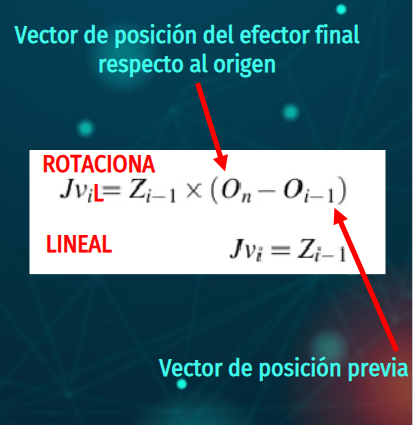

Fórmula 1.

Dependiendo del caso identificado, sea articulación rotacional o lineal, es la fórmula que se emplea.

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 
            % con respecto a 0 es la Matriz Identidad,
            % la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa 
            % se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1]; %tercera columna de la matriz identidad
        end
            Jw_a(:,k)=[0,0,0];
     end
end


#### Resultados

Para finalmente desplegar los resultados con simplify y pretty para tener una visualización más entendible.

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);

Resultado de las operaciones hechas en el ciclo for para obtener el jacobiano lineal con los movimientos lineales en l2, l3 y l1.

disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ 0, -1, 0 \
|          |
| 0,  0, 1 |
|          |
\ 1,  0, 0 /



Resultado del jacobiano angular obtenido de la forma analítica muestra, en este jacobiano, por no tener articulaciones que formen ángulos, ya que todas son prismáticas, la matriz aparece en ceros.

disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, 0, 0 \
|         |
| 0, 0, 0 |
|         |
\ 0, 0, 0 /



Al observar la velocidad lineal podemos comprobar que es correcto, porque tenemos movimiento en cada uno de los ejes x,y,z representado con la derivada en l1, l2 y l3  con respecto al tiempo, siendo la velocidad la derivada de la posición.

disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp);
pretty(V);

/    d          \
| - -- long2(t) |
|   dt          |
|               |
|   d           |
|  -- long3(t)  |
|  dt           |
|               |
|   d           |
|  -- long1(t)  |
\  dt           /



Nuevamente, por tener sólo articulaciones prismáticas obtenemos las siguientes velocidades angulares.

disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp);
pretty(W);

/ 0 \
|   |
| 0 |
|   |
\ 0 /



### **Energía cinética**

Se declara la distancia del origen del eslabón a su centro de masa con vectores de posición respecto al centro de masa.

posteriormente se crean la matrices de inercia por cada eslabón.

 P01=subs(P(:,:,1)/2, l1, lc1);
 P12=subs(P(:,:,2)/2, l2, lc2);
 P23=subs(P(:,:,3)/2, l3, lc3);

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

I2=[Ixx2 0 0; 
    0 Iyy2 0; 
    0 0 Izz2];

I3=[Ixx3 0 0; 
    0 Iyy3 0; 
    0 0 Izz3];


**Función de energía cinética**

%Extraemos las velocidades lineales en cada eje
V=V(t);
Vx= V(1,1);
Vy= V(2,1);
Vz= V(3,1);

%Extraemos las velocidades angular en cada ángulo de Euler
W=W(t);
W_pitch= W(1,1);
W_roll= W(2,1);
W_yaw= W(3,1);


**Calculamos las velocidades para cada eslabón**

Esta vez necesitamos obtener la velocidad lineal y angular del primer eslabón, ya que en este robot de dos grados de libertad previamente habíamos calculado las velocidades del último eslabón. A diferencia del robot péndulo, debemos que sacar individualmente las velocidades de cada eslabón.

%Eslabón 1

%Calculamos el jacobiano lineal de forma analítica
%se resta a los grados de libertad (3-2=1) para llegar al primer eslabón
Jv_a1(:,GDL-2)=PO(:,:,GDL-2);
Jw_a1(:,GDL-2)=PO(:,:,GDL-2);

for k= 1:GDL-2
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-2)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL-2));%Matriz de rotación de 0 
            % con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa se 
            % obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac1= [Jv_a1;
      Jw_a1];
Jacobiano1= simplify(Jac1);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares
 %disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1');
Qp=Qp(t);
V1=simplify (Jv_a1*Qp(1));
 %pretty(V1);
 % disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1');
W1=simplify (Jw_a1*Qp(1));
 % pretty(W1);


%Eslabón 2

%Calculamos el jacobiano lineal de forma analítica
%se resta a los grados de libertad (3-1=2) para llegar al segundo eslabón
Jv_a2(:,GDL-1)=PO(:,:,GDL-1);
Jw_a2(:,GDL-1)=PO(:,:,GDL-1);

for k= 1:GDL-1
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a2(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-1)-PO(:,:,k-1));
            Jw_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)= cross([0,0,1], PO(:,:,GDL-1));%Matriz de rotación de 0 con
            %respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a2(:,k)=[0,0,1];%Si no hay matriz de rotación previa se
            %obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)=[0,0,1];
        end
            Jw_a2(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a2= simplify (Jv_a2);
Jw_a2= simplify (Jw_a2);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac2= [Jv_a2;
      Jw_a2];
Jacobiano2= simplify(Jac2);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares
%disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 2');
V2=simplify (Jv_a2*Qp(1:2));
% pretty(V2);
%disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 2');
W2=simplify (Jw_a2*Qp(1:2));
%W2=zeros(3,1);
% pretty(W2);


**Energía cinética para cada eslabón**

Ahora si con las velocidades podemos obtener la energía cinética individual de cada elsabón. Se ocupan los vectores de distancia previamente declarados dependiendo de que eslabón se esté calculando.

%Eslabón 1
V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*(1/2*m1*(V1_Total)) + (1/2*W1)'*(I1*W1);
%disp('Energía Cinética en el Eslabón 1');
K1= simplify (K1);
%pretty (K1);

%Eslabón 2
V2_Total= V2+cross(W2,P12);
K2= (1/2*m2*(V2_Total))'*(1/2*m2*(V2_Total)) + (1/2*W2)'*(I2*W2);
%disp('Energía Cinética en el Eslabón 2');
K2= simplify (K2);
%pretty (K2);

%Eslabón 3
V3_Total= V+cross(W,P23);
K3= (1/2*m3*(V3_Total))'*(1/2*m3*(V3_Total)) + (1/2*W)'*(I3*W);
%disp('Energía Cinética en el Eslabón 3');
K3= simplify (K3);
%pretty (K3);


Sumamos las tres energías para desplegar la total

K_Total= simplify (K1+K2+K3);
pretty(K_Total)

 |  d          | 2     2       2 /  |  d          | 2    |  d          | 2    |  d          | 2 \       2 /  |  d          | 2    |  d          | 2 \
 | -- long1(t) |   |m1|    |m3|  |  | -- long1(t) |   +  | -- long2(t) |   +  | -- long3(t) |   |   |m2|  |  | -- long1(t) |   +  | -- long2(t) |   |
 | dt          |                 \  | dt          |      | dt          |      | dt          |   /         \  | dt          |      | dt          |   /
------------------------ + ---------------------------------------------------------------------- + -------------------------------------------------
            4                                                 4                                                             4



%se recopila el tiempo que tomó ejecutar las operaciones
toc

Elapsed time is 2.858066 seconds.
